clear;clc;close all
load('Amazonas.mat');

ydata = ydata(:, 10:end)';
ydata = [ydata(:,3), ydata(:,2), ydata(:,1)];

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta eta tau epsilon mu gamma k lambda nu z sigma

N = S + C + E + A + I + Q + R + D;

ode1 = diff(S) == -alpha*S - beta*I/N*S - sigma*S*A/N - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + beta*I/N*S + mu*C + eta*S + sigma*S*A/N - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(1,2) ydata(1,2);  %D    
            ydata(1,3) ydata(1,3);  %I
            7600 80000;             %S
            0 2000;                 %A
            0 1000;                 %C
            0 2000;                 %E
            0 2000                  %Q
];

Range2 = [  0 2;    %alpha
            0 10;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu
            0 10;   %sigma    
            0 6;    %tau
]; 

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1,3];
[T,~] = gsua_dpmat(odes,vars,[0 90],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{ccccccccccccccccccc} R\left(t\right) & \text{D}\left(t\right) & \text{I}\left(t\right) & S\left(t\right) & A\left(t\right) & C\left(t\right) & \text{E}\left(t\right) & Q\left(t\right) & \alpha & \beta & \delta & \epsilon & \eta & \gamma & k & \lambda & \mu & \sigma & \tau \end{array}\right)$$

% domain=[0 90 0.01]%add a third column with fixed step size to domain variable
% [T,sol] = gsua_dataprep(odes,vars,domain,'Model','solver','ode4');
T.Row = ["S(0)", "A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", "\lambda", "\mu", "\sigma",  "\tau"];

Define the nominal curve as the best factor estimation

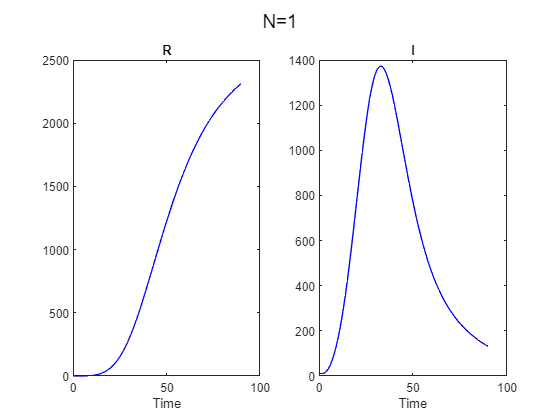

load('Results/Estimations/Deepest_Amazonas.mat')
T.Nominal = Deep;
[ydata,xdata]=gsua_eval(T.Nominal,T);

Tia=gsua_likelihood(T,xdata,[],0.95,0.05,1.3,0.5,0.001,100,1,true,false,true,[]);

Sim100 Done
Sim99 Done
Sim98 Done
Sim97 Done
Sim96 Done
Sim95 Done
Sim94 Done
Sim93 Done
Sim92 Done
Sim91 Done
Sim90 Done
Sim89 Done
Sim88 Done
Sim87 Done
Sim86 Done
Sim85 Done
Sim84 Done
Sim83 Done
Sim82 Done
Sim81 Done
Sim80 Done
Sim79 Done
Sim78 Done
Sim77 Done
Sim76 Done
Sim75 Done
Sim74 Done
Sim73 Done
Sim72 Done
Sim71 Done
Sim70 Done
Sim69 Done
Sim68 Done
Sim67 Done
Sim66 Done
Sim65 Done
Sim64 Done
Sim63 Done
Sim62 Done
Sim61 Done
Sim60 Done
Sim59 Done
Sim58 Done
Sim57 Done
Sim56 Done
Sim55 Done
Sim54 Done
Sim53 Done
Sim52 Done
Sim51 Done
Sim50 Done
Sim49 Done
Sim48 Done
Sim47 Done
Sim46 Done
Sim45 Done
Sim44 Done
Sim43 Done
Sim42 Done
Sim41 Done
Sim40 Done
Sim39 Done
Sim38 Done
Sim37 Done
Sim36 Done
Sim35 Done
Sim34 Done
Sim33 Done
Sim32 Done
Sim31 Done
Sim30 Done
Sim29 Done
Sim28 Done
Sim27 Done
Sim26 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim21 Done
Sim20 Done
Sim19 Done
Sim18 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim14 Done
Sim13 Done
Sim12 Done
Sim11 Done
Sim10 Don

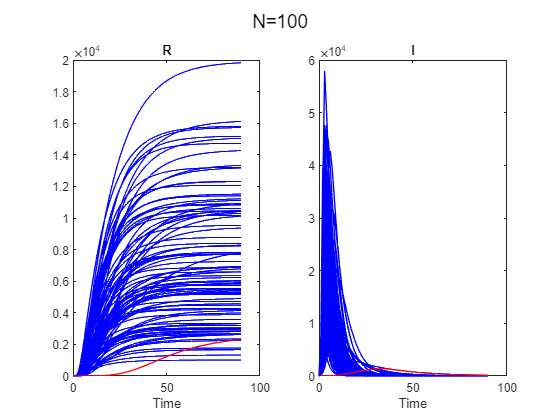

M=gsua_dmatrix(Tia,100);
gsua_eval(M',Tia,xdata,ydata);